# Laboratoire 3 : Synthétiser un régulateur discret de compensation

# Système idéal

Le modèle de référence devra satisfaire aux exigences suivantes :

- un temps de réponse à 5% = 1 s (3T)

- Un dépassement maximum de 5%

Les pôles d'un système présentant ces caractéristiques peuvent être récupérés avec la fonction  *dtr2ord2o.*

clear all;
p = dtr2ord2o(1,5,5);

On construit la fonction de transfert du système en utilisant les pôles précédemment trouvés pour le dénominateur. Pour avoir un gain unitaire on utilisera le terme indépendant du dénominateur comme numérateur.

DTfc = poly(p);
NTfc = DTfc(3);
Fc = tf(NTfc,DTfc);

On peut désormais, discrétiser notre système (Periode d'échantillonnage = 0,1s)

h = 0.1;
pd = exp(p*h);
Fd = c2d(Fc,h)


Fd =
 
   0.07675 z + 0.06281
  ---------------------
  z^2 - 1.41 z + 0.5493
 
Sample time: 0.1 seconds
Discrete-time transfer function.



## Réponse indicielle

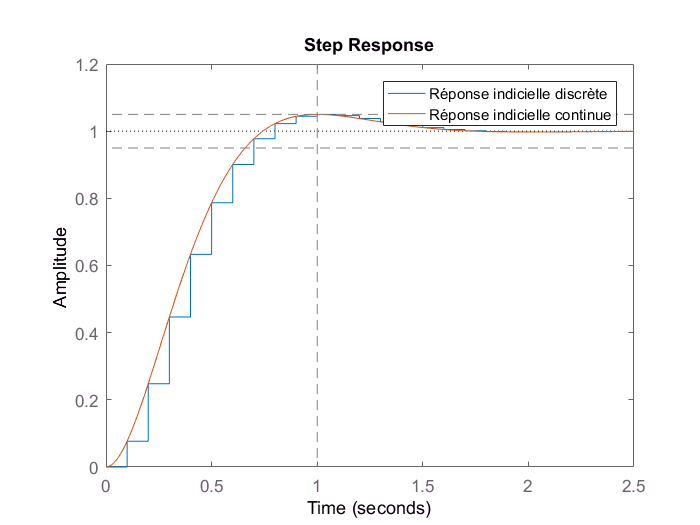

figure;
hold on
step(Fd);
step(Fc);
linecolor = [0.5 0.5 0.5];
line([0 5],[0.95 0.95],'Color',linecolor,'LineStyle','--')
line([0 5],[1.05 1.05],'Color',linecolor,'LineStyle','--')
line([1 1],[0 3],'Color',linecolor,'LineStyle','--')
legend('Réponse indicielle discrète','Réponse indicielle continue')

## Poles et zéros

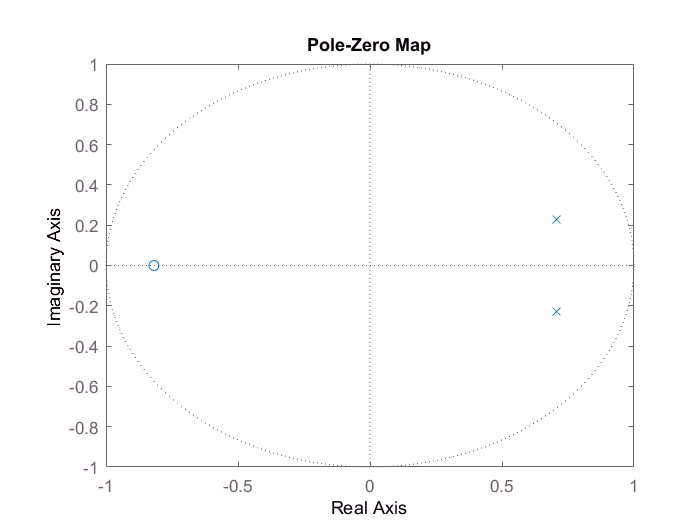

figure;
pzmap(Fd);

# Système réel (paramétrique)

## La transmittance du système réel : 

La transmittance du système est imposée et  vaut : 


$$\mathrm{Tc}=\frac{1}{s\left(s+0\ldotp 5\right)}$$


Une fois échantillonée (période déchantillonage = 0,1s), cette même transmittance peut s'écrire sous la forme : 


$$\mathrm{Td}=\text{ }\frac{1}{\left(z-1\right)\left(z-p\right)}$$


On notera que la transmittance réelle sera adjoint d'un zéro (nommé *t*) et d'un gain (nommé *k*) amenés par le délai dû à la méthode d'échantillonnage. La transmittance peut se réécrire : 


$$\mathrm{Td}=\frac{k\left(z-t\right)}{\left(z-1\right)\left(z-p\right)}$$


## Le régulateur.

L'objectif du régulateur est d'essayer de neutraliser les effets indésirables amenés par l'échantillonage. Dans l'idéal, le régulateur compenserait le délai de la transmittance ainsi que le pôle *p *et serait de la forme : 


$$R=\text{ }\frac{\left(z-p\right)}{k\left(z-t\right)}$$


Cependant, on introduit un zéro $\left(z-r\right)$ dans notre régulateur. De cette manière on peut imposer le temps de réponse et le dépassement. De plus on placera un deuxième intégrateur dans la chaine directe pour avoir une erreur de vitesse nulle. Au final, notre régulateur aura pour transmittance :


$$R=\frac{K\left(z-r\right)\left(z-p\right)}{k\left(z-t\right)\left(z-1\right)}$$


## Le système 

Comme le régulateur compense les pôles (à l'exception de l'intégrateur), le zero et le gain de la transmittance notre système en boucle ouverte à pour équation :


$$\mathrm{Bo}=\frac{k\left(z-t\right)K\left(z-r\right)\left(z-p\right)}{\left(z-1\right)\left(z-p\right)k\left(z-t\right)\left(z-1\right)}=\frac{K\left(z-r\right)}{{\left(z-1\right)}^2 }$$
  

Ce qui donne comme équation en boucle fermée :


$$\mathrm{Bf}=\frac{K\left(z-r\right)}{{\left(z-1\right)}^2 +K\left(z-r\right)}\text{ }$$


# Recherche de la valeur des paramètres

L'objectif étant d'avoir un système répondant aux mêmes critères que le système idéal, les pôles de la boucle fermée (racines de l'équation caractéristique) doivent être égaux aux pôles du système idéal. Il s'agit ni plus ni moins d'un système de deux équations à deux inconnues. Pour résoudre ce dernier, nous utiliserons le calcul symbolique que nous fournit Matlab.

syms z t r p K k;
Transmittance = k*(z - t)/((z-1)*(z-p));
Regu1ator     = K*(z - p)*(z - r)/(k*(z - t)*(z - 1));
Bo = Transmittance*Regu1ator;
Bf = Bo/(1+Bo);

La fonction *poles* nous permet d'extraire les pôles de la boucle fermée sous la forme paramétrique. Ensuite nous égalons les pôles paramétriques aux pôles attendus.

PoleBF = poles(Bf,z);
PoleBF(1) = PoleBF(1) == pd(1);
PoleBF(2) = PoleBF(2) == pd(2);

La fonction *solve* permet alors de résoudre le système de deux équations à deux inconnues que nous venons de construire

Param = solve(PoleBF);

Nous pouvons à présent construire la fonction de transfert caractérisant notre système, en remplaçant dans la boucle fermée les paramètres par leur valeur numérique

z = tf('z',h);
K = double(Param.K);
r = double(Param.r);
Bf = (K*(z - r))/((z - 1)^2+K*(z - r));
Bf1 = minreal(Bf)


Bf1 =
 
    0.5903 z - 0.4507
  ---------------------
  z^2 - 1.41 z + 0.5493
 
Sample time: 0.1 seconds
Discrete-time transfer function.



# Présentation des résulats

## Réponse indicelle

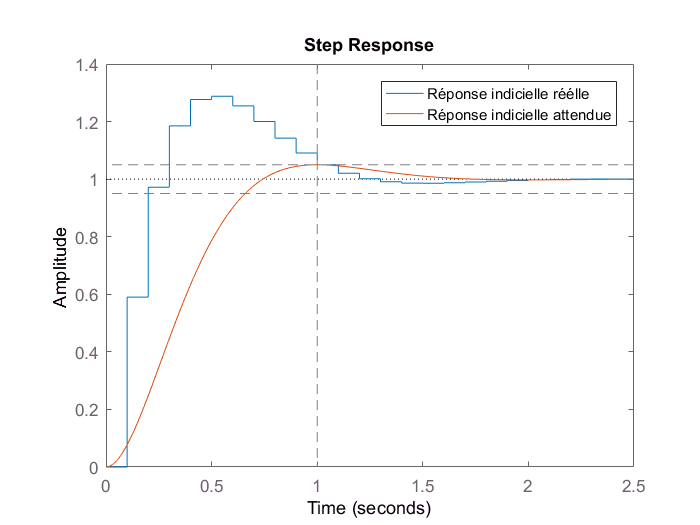

figure;
hold on
title('Comparaison entre la réponse indicielle du système idéal et réel');
step(Bf1);
step(Fc);
linecolor = [0.5 0.5 0.5];
line([0 5],[0.95 0.95],'Color',linecolor,'LineStyle','--');
line([0 5],[1.05 1.05],'Color',linecolor,'LineStyle','--');
line([1 1],[0 3],'Color',linecolor,'LineStyle','--');
legend('Réponse indicielle réelle','Réponse indicielle attendue')

## Pôles et zéros

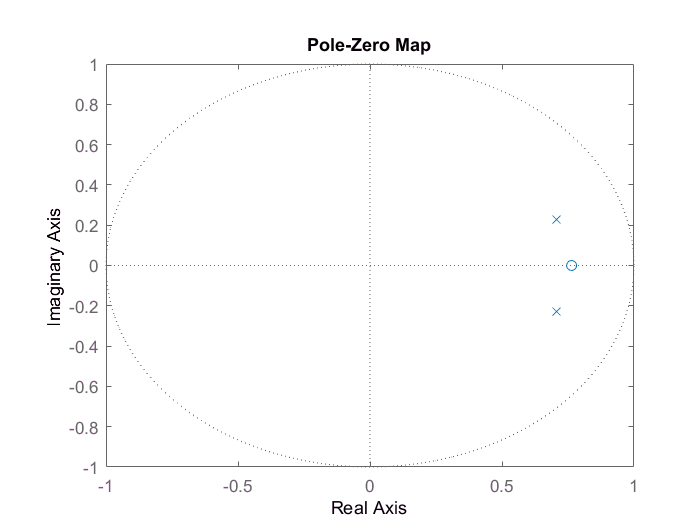

figure;
title('Représentation des pôles et des zéros du système');
pzmap(Bf1)

## Observations

- On observe sur le graphique de la réponse à un échelon que le temps de réponse à 95% de 1s attendu est bien respecté par le système régulé

- Par contre, le dépassement maximum de 5% est dépassé. Cette caractéristique peut être due à l'échantillonnage ainsi qu'à l'ajout d'intégrateur dans le système par le régulateur

# Regulateur modifié

Dans un deuxième temps, nous avons réalisé un régulateur qui ne compense plus le zéro du système :


$$R=\frac{K\left(z-r\right)\left(z-p\right)}{k\left(z-1\right)}$$


Ce régulateur présente un problème de faisabilité physique : le degré du numérateur est supérieur au degré du numérateur. On introduira donc un pôle supplémentaire nommé *ps :*


$$R=\frac{K\left(z-r\right)\left(z-p\right)}{k\left(z-1\right)\left(z-\mathrm{ps}\right)}$$


notre système en boucle ouverte vaut désormais:


$$\text{Bo}=\frac{k\left(z-t\right)K\left(z-r\right)\left(z-p\right)}{\left(z-1\right)\left(z-p\right)k\left(z-1\right)\left(z-\mathrm{ps}\right)}=\frac{K\left(z-r\right)\left(z-t\right)}{{\left(z-1\right)}^2 \left(z-\mathrm{ps}\right)}$$


Et lorsque l'on applique la rétroaction :


$$\text{Bf}=\frac{K\left(z-r\right)\left(z-t\right)}{{\left(z-1\right)}^2 \left(z-\mathrm{ps}\right)+K\left(z-r\right)\left(z-t\right)}\text{ }$$


Dans ce cas ci, on se retrouve avec 4 inconnues, il faudra donc trouver 4 équations. Pour ce faire, on égalera les coefficients de l'équation caractéristique avec ceux de l'équation caractéristique souhaitée. Comme ces équations sont de degré différent, on appliquera la méthode du pôle dominant pour imposer la position du troisième pôle, 5 fois plus rapide que celui du second ordre fondamental (partie réelle des pôles complexes conjugués imposée au travers du temps de réponse et du dépassement)

syms x ps K r t;
eqC = (x - 1)^2*(x - ps) + K*(x - r)*(x - t);
coefEqC = coeffs(eqC,x);
desiredEqC = (x - pd(1))*(x - pd(2))*(x - real(pd(1)/5));
coefDesiredEqC = coeffs(desiredEqC,x);

Comme les équations sont de degré 3, nous obtenons 4 coefficients. Nous pouvons maintenant construire notre système de 4 équations à 4 inconnues et le résoudre

Sys(1) = coefEqC(1) == coefDesiredEqC(1);
Sys(2) = coefEqC(2) == coefDesiredEqC(2); 
Sys(3) = coefEqC(3) == coefDesiredEqC(3);
Sys(4) = coefEqC(4) == coefDesiredEqC(4);
Data = solve(Sys);

Il est alors possible de construire la fonction de transfert caractérisant notre système en remplaçant dans la boucle fermée les paramètres par leur valeur numérique

K  = double(Data.K);
ps = double(Data.ps);
r  = double(Data.r);
t  = double(Data.t);

Bf = K*(z - r)*(z - t)/((z - 1)^2*(z - ps) + K*(z - r)*(z - t));
Bf2 = minreal(Bf)


Bf2 =
 
         0.5267 z^2 - 0.4069 z
  -----------------------------------
  z^3 - 1.551 z^2 + 0.748 z - 0.07743
 
Sample time: 0.1 seconds
Discrete-time transfer function.



# Présentation des résultats

## Réponse indicielle

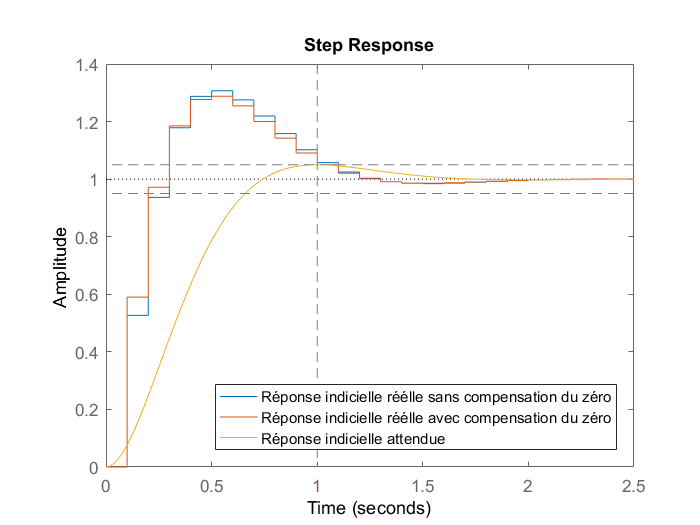

figure;
hold on
title('Comparaison entre la réponse indicielle du système idéal et réel');
step(Bf2);
step(Bf1);
step(Fc);
linecolor = [0.5 0.5 0.5];
line([0 5],[0.95 0.95],'Color',linecolor,'LineStyle','--');
line([0 5],[1.05 1.05],'Color',linecolor,'LineStyle','--');
line([1 1],[0 3],'Color',linecolor,'LineStyle','--');
legend('Réponse indicielle réelle sans compensation du zéro', 'Réponse indicielle réelle avec compensation du zéro', 'Réponse indicielle attendue', 'Location', 'southeast')

## Pôles et zéros

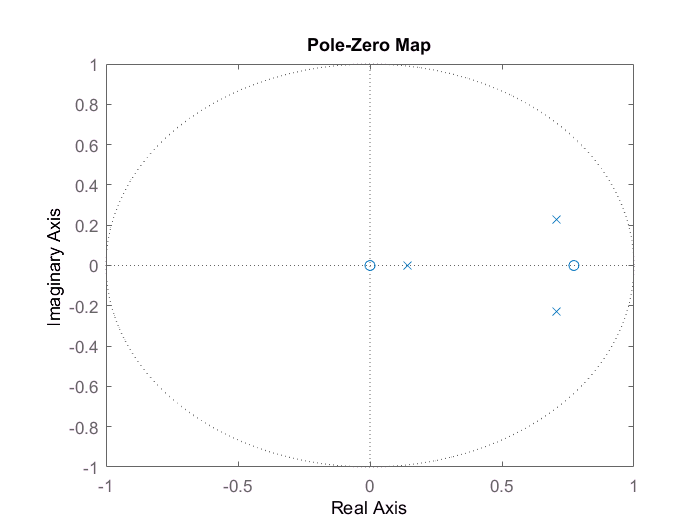

figure;
title('Réprésentation des pôles et des zéros du système');
pzmap(Bf2)

## Observations

- Nous observons que la réponse indicielle du système avec le régulateur sans compensation du zéro est très proche de la réponse du système avec le régulateur sans compensation de zéro (au niveau du dépassement et du temps de réponse). Les raisons avancées pour le premier régulateur sont donc valables une nouvelle fois ici

- Cependant, nous constatons une différence légère entre les deux réponses des systèmes régulés. Cette différence peut être expliquée par l'ajout d'un pôle supplémentaire par rapport à la première forme du régulateur construit dans plus tôt dans la séance. Malgré ce pôle supplémentaire, son influence reste limitée et ce par la dominance des deux autres pôles.